E=1;
I=1;
L=1;
r=1;
p=1;
%A = (E*I/L^3) * [r 0 0 -r 0 0; 0 12 6*L 0 -12 6*L; 0 6*L 4*L^2 0 -6*L 2*L^2; -r 0 0 r 0 0; 0 -12 -6*L 0 12 -6*L; 0 6*L 2*L^2 0 -6*L 4*L^2];
K = [12, 6*L, -12, 6*L; 6*L, 4*L^2, -6*L, 2*L^2; -12, -6*L, 12, -6*L; 6*L, 2*L^2, -6*L, 4*L^2];
L=-p*L*[-1/6;L/12;1/2;-L/12];

%matrices sur 2L
K2=zeros(6,6);
K2(1:4,1:4)=K;
K2(3:6,3:6)=K2(3:6,3:6)+K;

L2=zeros(6,1);
L2(1:4)=L;
L2(3:6)=L2(3:6)+L;

%matrice L2
L2(1)=0;%u1=0
L2(2)=0;%theta1=0
L2(5)=0;%u3=1
L2(6)=0;%theta3=0

%%matrice K2
%lignes
K2(1,:)=zeros(1,6);%u1=0
K2(2,:)=zeros(1,6);%theta1=0
K2(5,:)=zeros(1,6);%u3=0
K2(6,:)=zeros(1,6);%theta3=0

%colonnes
K2(:,1)=zeros(6,1);%u1=0
K2(:,2)=zeros(6,1);%theta1=0
K2(:,5)=zeros(6,1);%u3=0
K2(:,6)=zeros(6,1);%theta3=0

%solution
U=zeros(6,1);
U(3:4)=2*inv(K2(3:4,3:4))*L2(3:4);

## 4 Hermitian elements

%Matrice 4L
K4=zeros(10,10);
K4(1:4,1:4)=K;
K4(3:6,3:6)=K4(3:6,3:6)+K;
K4(5:8,5:8)=K4(5:8,5:8)+K;
K4(7:10,7:10)=K4(7:10,7:10)+K;

L4=zeros(10,1);
L4(1:4)=L;
L4(3:6)=L4(3:6)+L;
L4(5:8)=L4(5:8)+L;
L4(7:10)=L4(7:10)+L;

%BC
%matrice L4
L4(1)=0;%u1=0
L4(2)=0;%theta1=0
L4(9)=0;%u5=1
L4(10)=0;%theta5=0


%%matrice K4
%lignes
K4(1,:)=zeros(1,10);%u1=0
K4(2,:)=zeros(1,10);%theta1=0
K4(9,:)=zeros(1,10);%u5=0
K4(10,:)=zeros(1,10);%theta5=0

%colonnes
K4(:,1)=zeros(10,1);%u1=0
K4(:,2)=zeros(10,1);%theta1=0
K4(:,9)=zeros(10,1);%u5=0
K4(:,10)=zeros(10,1);%theta5=0

%solution
U4=zeros(10,1);
U4(3:8)=2*inv(K4(3:8,3:8))*L4(3:8);


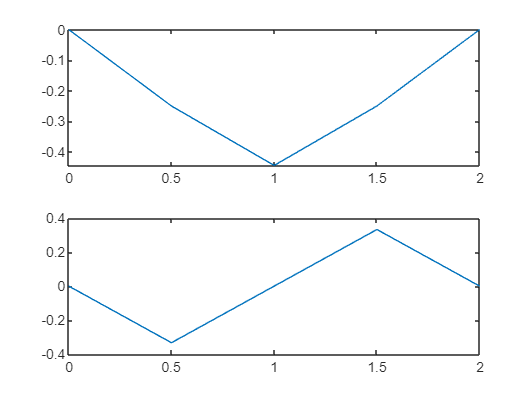

% Données d'entrée
x = [0, 1/2, 1, 3/2 ,2];
y = [U4(1), U4(3), U4(5), U4(7), U4(9)];
dy = [U4(2), U4(4), U4(6), U4(8), U4(10)];
figure,
subplot(2,1,1)
plot(x,y)
subplot(2,1,2)
plot(x,dy)


N1=@(x)((x-1)^2*(2*x+1));
N2=@(x)(L*x*(x-1)^2);
N3=@(x)(x^2*(-2*x+3));
N4=@(x)(L*x^2*(x-1));

X=linspace(0,1,10);
U41=U4(1)*N1(X)+U4(2)*N2(X)+U4(3)*N3(X)+U4(4)*N4(X);

Error using  ^  (line 52)
Incorrect dimensions for raising a matrix to a power. Check that the matrix is square and the power is a scalar. To perform elementwise matrix powers, use '.^'.

Error in TD5 (line 89)
N1=@(x)((x-1)^2*(2*x+1));